# **两次优化**

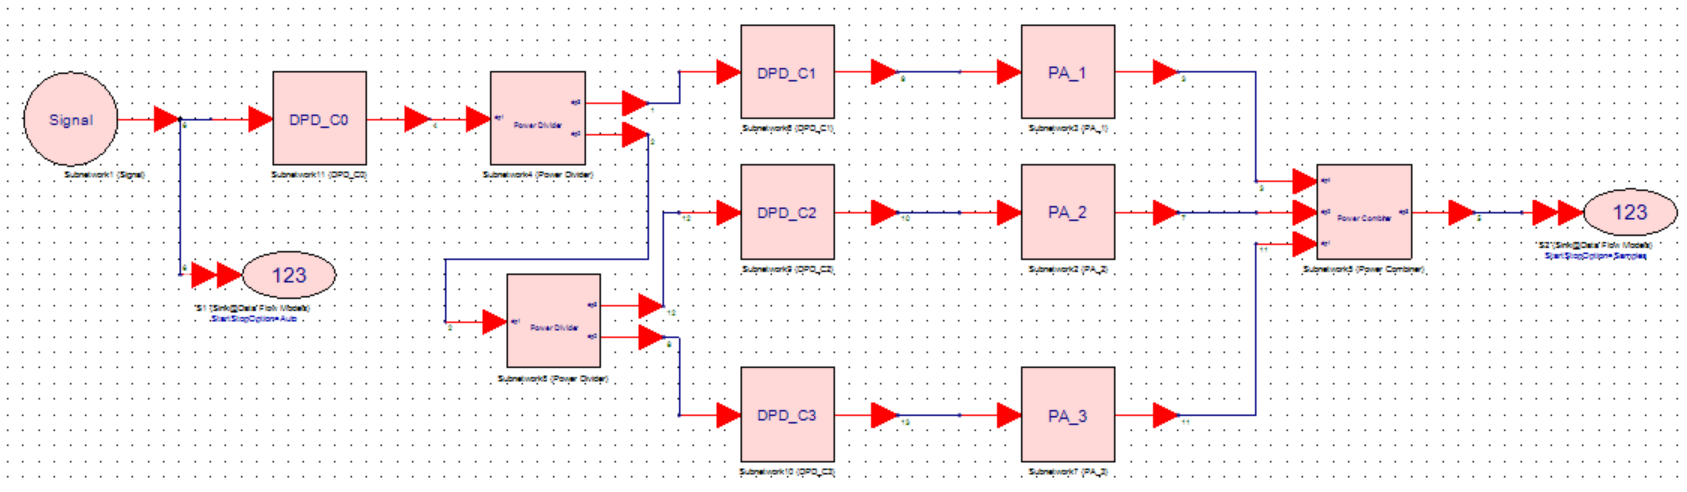

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model C Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4); 
PA2_output = Data_matrix(:,5) + 1i * Data_matrix(:,6); 
PA3_output = Data_matrix(:,7) + 1i * Data_matrix(:,8); 
PA1_input = 0.5*Sys_input;
PA2_input = 0.25*Sys_input;
PA3_input = 0.25*Sys_input;
% 参数需要保持一致
M = 4; 

## 【训练PA3】

% % 模型训练
% model=Train_PA3(M,dim,PA3_input,PA3_output);
% save('Method_C\PA3\N1.mat', 'model');

## 【训练PA2】

% % 模型训练
% model=Train_PA2(M,dim,PA2_input,PA2_output);
% save('Method_C\PA2\N1.mat', 'model');

## 【训练PA1】

% % 模型训练
% model=Train_PA1(M,dim,PA1_input,PA1_output);
% save('Method_C\PA1\N1.mat', 'model');

## 第一次迭代

% 系统仿真
[A1_input,A23] = Power_Divider(Sys_input);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_predict(A1_input,M,'Method_C\PA1\N1.mat');
% A1_input_DPD2 = DPD_sim(A1_input_DPD1,M,'Method_C\PA1\FNN.mat');
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_predict(A2_input,M,'Method_C\PA2\N1.mat');
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_predict(A3_input,M,'Method_C\PA3\N1.mat');
A3_output = PA_3(A3_input_DPD);
Sys_output_middle = Power_Combiner(A1_output,A2_output,A3_output);
% 中间评估
nmse_middle = NMSE_dB(Sys_input,Sys_output_middle)

nmse_middle = -31.6404

nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = -27.8712

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -33.7666

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -32.2732

## 【训练】整体优化

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０１　｜　　　　　　　１．３７　｜　　　　　　１．２７　｜　　０．９３６７　｜　０．８０１５　｜　　０．００５０　｜
｜　　４０　｜　　　４０　｜　　　　　００：００：０１　｜　　　　　　　０．３０　｜　　　　　　０．２７　｜　　０．０４３９　｜　０．０３７７　｜　　０．００５０　｜
｜　　８０　｜　　　８０　｜　　　　　００：００：０１　｜　　　　　　　０．０８　｜　　　　　　０．０７　｜　　０．００２８　｜　０．００２６　｜　　０．００５０　｜
｜　１２０　｜　　１２０　｜　　　　　００：００：０２　｜　　　　　　　０．０５　｜　　　　　　０．０５　｜　　０．００１２　｜　０．００１２　｜　　０．００５０　｜
｜　１６０　｜　　１６０　｜　　　　　００：００：０２　｜　　　　　　　０．０４　｜　　　　　　０．０４　｜　　０．０００８　｜　０．０００７　｜　　０．００５０　｜
｜　２００　｜　　２００　｜　　　　　００：００：０２　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００６　｜　０．０００６　｜　　０．００５０　｜
｜　２４０　｜　　２４０　｜　　　　　００：００：０３　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００５　｜　０．０００５　｜　　０．００５０　｜
｜　２８０　｜　　２８０　｜　　　　　００：００：０３　｜　　　　　　　０．０３　｜　　　　　　０．０３　｜　　０．０００４　｜　０．０００４　｜　　０

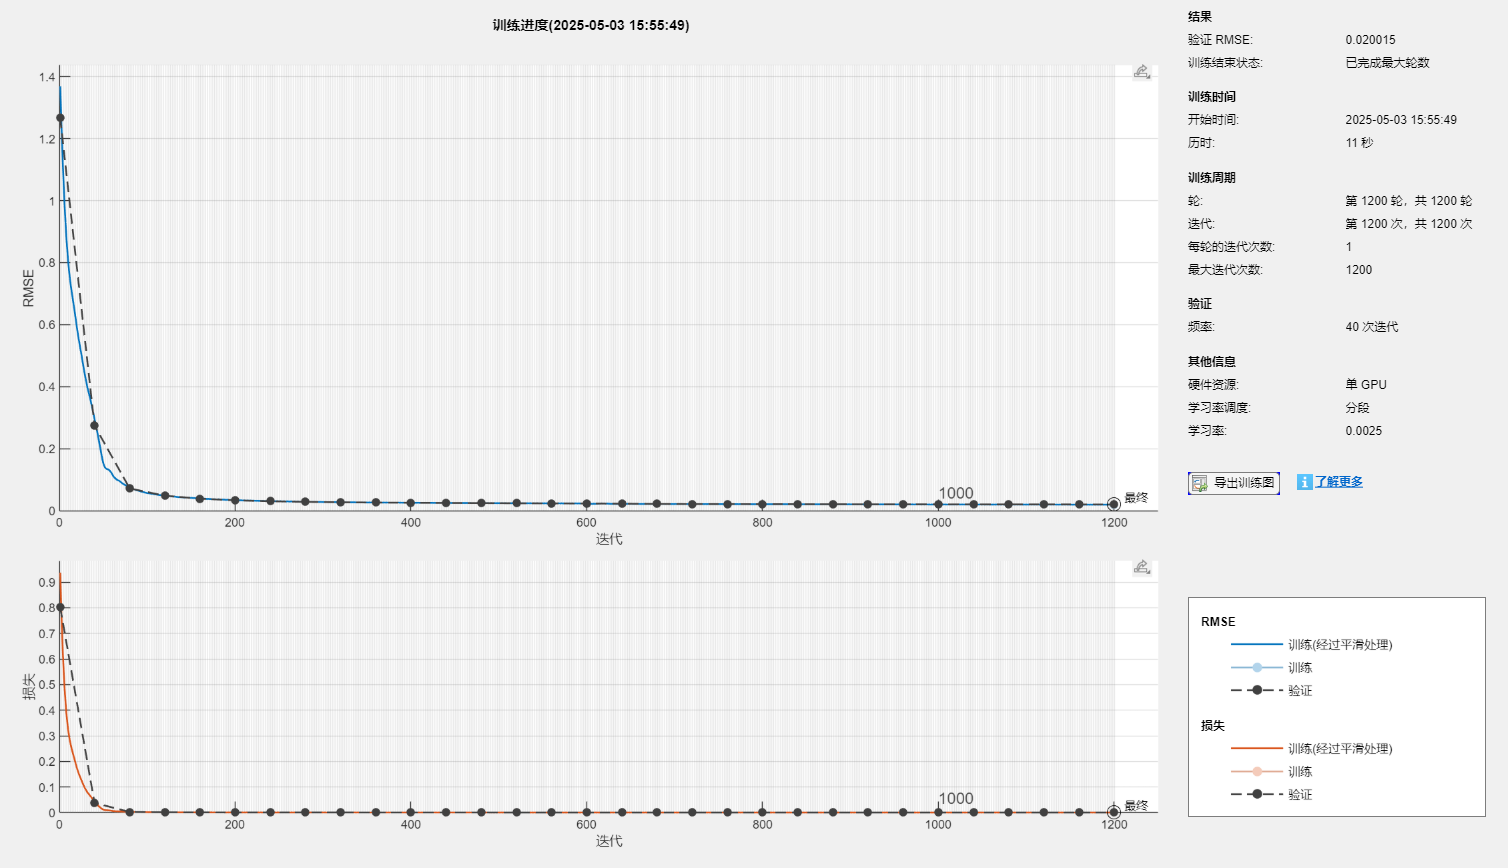

% 模型训练
model=Train_Whole(M,dim,Sys_input,Sys_output_middle);

save('Method_C\Whole\N1.mat', 'model');

## Model Test

% 系统仿真
Sys_input_DPD=DPD_predict(Sys_input,M,'Method_C\Whole\N1.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_predict(A1_input,M,'Method_C\PA1\N1.mat'); % DPD
% A1_input_DPD2 = DPD_sim(A1_input_DPD1,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_predict(A2_input,M,'Method_C\PA2\N1.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_predict(A3_input,M,'Method_C\PA3\N1.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
nmse = NMSE_dB(Sys_input,Sys_output);
nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = -26.7046

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -33.7550

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -32.1410

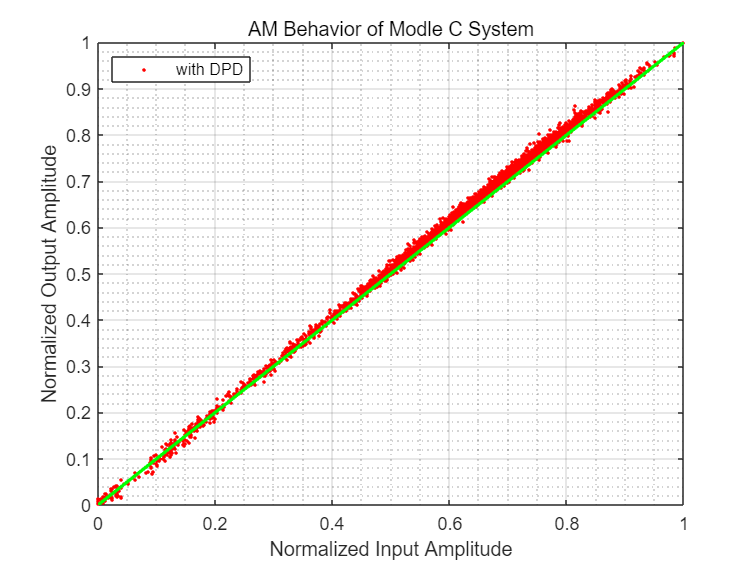

Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD');

fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse);

使用Model C，系统的NMSE仿真结果为 -31.995995 dB


## -----------------------------Model C Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 4;

## Model Test

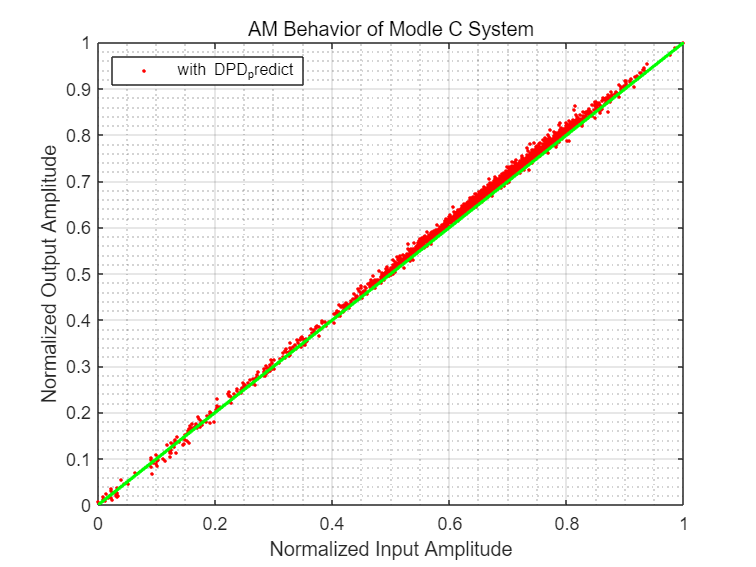

% 系统仿真
Sys_input_DPD=DPD_predict(Sys_input,M,'Method_C\Whole\N1.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD1 = DPD_predict(A1_input,M,'Method_C\PA1\N1.mat'); % DPD
% A1_input_DPD2 = DPD_sim(A1_input_DPD1,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD1);
A2_input_DPD = DPD_predict(A2_input,M,'Method_C\PA2\N1.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_predict(A3_input,M,'Method_C\PA3\N1.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+2M）个值
Sys_input = Sys_input(5+M*2:end);
Sys_output = Sys_output(5+M*2:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD_predict');

nmse_sim= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model C，系统的NMSE仿真结果为 -32.055266 dB
